# A simulation of a BBM92 satellite pass.

## 1. Construct components

%1.1.1 Source
transmitter_source = components.Source( ...
    780,... %emission wavelength in nm
   'Repetition_Rate', 1E8,... %overriding default repetition rate in Hz
   'MPN_Signal', 0.1); %overriding default MPN

%1.1.2 Detector
% Need to provide repetition rate in order to compute QBER and loss due to
% time gating
detector = components.Detector( ...
    transmitter_source.wavelength,... %need to specify wavelength in nm for efficiency calculation
    transmitter_source.repetition_rate,... %need to provide rep rate so that jitter can be calculated
    1E-9,... %Time gate width of detector in s
    10,... % spectral filter width applied to detector (can also replace with more complex Spectral_Filter object)
    'Preset', 'PerkinElmer'); %using Perkin Elmer preset for jitter and efficiency graphs

%1.1.3 Transmitter telescope
transmitter_telescope = components.Telescope(0.1); % diameter of telescope in m
%using default 1urad for pointing jtter and calculating diffraction-limited FOV 

%1.1.4 Receiver telescope
receiver_telescope = components.Telescope( ...
    1, ... %diameter of telescope in m
    'FOV', 10E-6,... %choosing to specify FOV here. pointing error is 1urad by default
    'Wavelength', transmitter_source.wavelength); %specifying FOV requires specifying wavelength

%1.2.1 Construct satellite
SimSatellite=nodes.Satellite( ...
    transmitter_telescope, ...
    'Source', transmitter_source,...
    'Detector', detector, ... %the transmitter satellite needs an on-detector for the BBM92 protocol
    'OrbitDataFileLocation', '500kmSSOrbitLLAT.txt'); %specifying a preset orbit to avoid having to faff with keplerian orbital description

%1.2.2 construct ground station, use Heriot-Watt as an example
SimGround_Station=nodes.GroundStation( ...
    receiver_telescope,...
    'Detector', detector,...
    'LLA', [55.909723, -3.319995,10],...
    'Name', 'Heriot-Watt');

## 2 run

%2.1 run simulation
Result = nodes.qkdPassSimulation(SimGround_Station, SimSatellite, protocol.BBM92);


## 3 Plot results

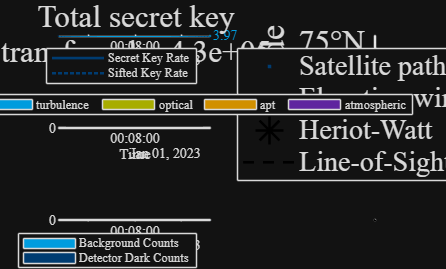

ans =   Figure (3: Point-to-Point BBM92 simulation from Unnamed Satellite to Heriot-Watt) with properties:

      Number: 3
        Name: 'Point-to-Point BBM92 simulation from Unnamed Satellite to Heriot-Watt'
       Color: [0.0706 0.0706 0.0706]
    Position: [423 230 560 337.3557]
       Units: 'pixels'

  Show all properties


%2.2 plot results
Result.plot()